nx1 = 0 : 9;
nh1 = 0 : 4;

x = [ones(1, 5), zeros(1, 5)];
h1 = [1, -1, 3, 0, 1];

nw = nx1;
w = (nx1 + 1) .* x;

ny = nw(1) + nh1(1) : nw(end) + nh1(end);
yf1 = conv(w, h1);

nd = 0 : 4;
delta = [1, zeros(1, 4)];

nhf1 = nd;
hf1 = (nd + 1) .* delta;

nh_series = nhf1(1) + nh1(1) : nhf1(end) + nh1(end);
h_series = conv(hf1, h1);

nyf2 = nh_series(1) + nx1(1) : nh_series(end) + nx1(end);
yf2 = conv(x, h_series);

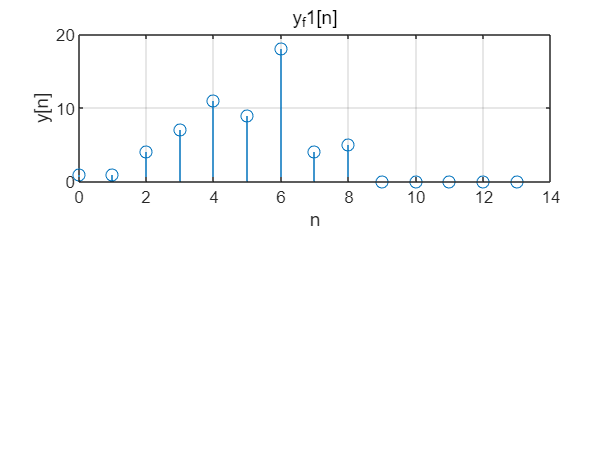

subplot(2, 1, 1);
stem(ny, yf1);
title("y_f1[n]");
xlabel("n")
ylabel("y[n]");
grid on;

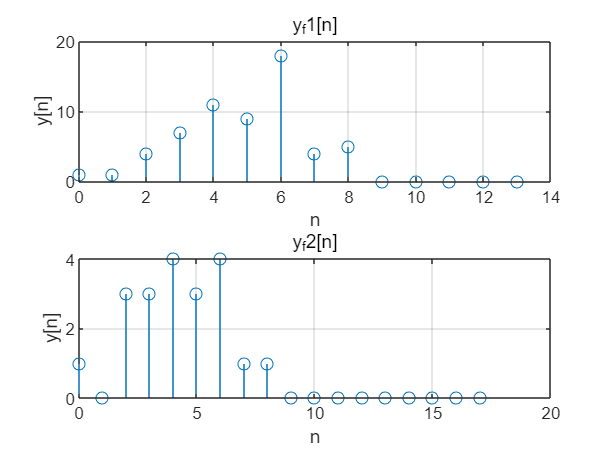

subplot(2, 1, 2);
stem(nyf2, yf2);
title("y_f2[n]");
xlabel("n")
ylabel("y[n]");
grid on;